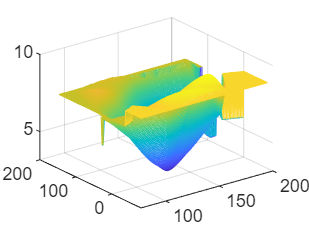

x0 = [129,140,103.5,88,185.5,195,105,157.5,107.5,77,81,162,162,117.5];
y0 = [1.5,141.5,23,147,22.5,137.5,85.5,-6.5,-81,3,56.5,-66.5,84,-33.5];
z0 = [4,8,6,8,6,8,8,9,9,8,8,9,4,9];
xmm = minmax(x0);
ymm = minmax(y0);
x = xmm(1):xmm(2);
y = ymm(1):ymm(2);
z1 = griddata(x0,y0,z0,x,y','cubic'); %立方插值  注意要写成y'倒置一下
z2 = griddata(x0,y0,z0,x,y','nearest');%最近点插值
%立方插值会有不确定值NaN，所以组合成混合插值
z =z1;  %先让混合值等于立方插值
z(isnan(z1))=z2(isnan(z1)); %再在不确定值的位置用
mesh(x,y,z)